% --- 1. Definicja modelu ciągłego ---
% Licznik (num) i Mianownik (den) z Twojego równania
num = [-5.5, -0.1];
den = [0.0344, 0.1783, -2.5651, -0.1472];

% Utworzenie transmitancji ciągłej G(s)
Gs = tf(num, den);

% Sprawdzenie biegunów (zobaczysz, że są w prawej półpłaszczyźnie - niestabilne)
disp('Bieguny układu ciągłego:');

Bieguny układu ciągłego:


disp(pole(Gs));

  -11.5868
    6.4608
   -0.0572



% --- 2. Dyskretyzacja ---
Ts = 0.001; % Czas próbkowania [s] (możesz spróbować zmienić na 0.005)

% Dyskretyzacja metodą ZOH (ekstrapolator rzędu zerowego)
Gz = c2d(Gs, Ts, 'zoh');

disp('Transmitancja dyskretna G(z):');

Transmitancja dyskretna G(z):


disp(Gz);

  tf with properties:

       Numerator: {[0 -7.9805e-05 1.3583e-07 7.9666e-05]}
     Denominator: {[1 -2.9949 2.9897 -0.9948]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.0000e-03
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



opts = pidtuneOptions('DesignFocus', 'reference-tracking');

% Automatyczne strojenie dla obiektu dyskretnego Gz
% MATLAB spróbuje znaleźć stabilizujące nastawy
[C_pid, info] = pidtune(Gz, 'PID', opts);

disp('Wyliczone nastawy PID:');

Wyliczone nastawy PID:


disp(C_pid);

  pid with properties:

              Kp: -0.6192
              Ki: -0.0078
              Kd: -12.2752
              Tf: 0
        IFormula: 'ForwardEuler'
        DFormula: 'ForwardEuler'
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.0000e-03
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Wyświetlenie parametrów jakości regulacji (np. margines fazy)
disp(['Margines fazy: ', num2str(info.PhaseMargin)]);

Margines fazy: NaN


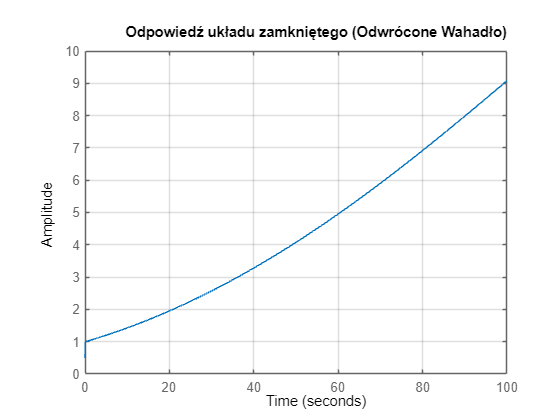

% --- 4. Symulacja pętli zamkniętej ---
% Układ zamknięty: Feedback(Regulator * Obiekt, 1)
Sys_cl = feedback(C_pid * Gz, 1);

% Symulacja odpowiedzi na skok jednostkowy (wymuszenie kąta)
figure;
step(Sys_cl);
title('Odpowiedź układu zamkniętego (Odwrócone Wahadło)');
grid on;

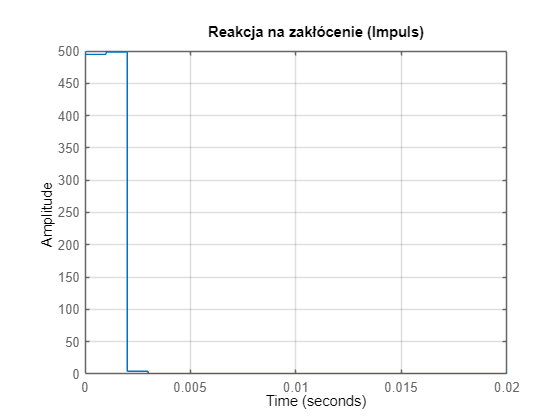


% Opcjonalnie: Odpowiedź na impuls (symulacja uderzenia w wahadło)
figure;
impulse(Sys_cl);
title('Reakcja na zakłócenie (Impuls)');
grid on;

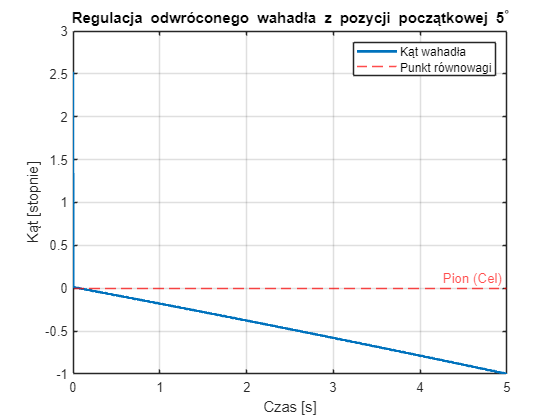


angle_initial = 5; % Wychylenie początkowe [stopnie]
t_sim = 0:Ts:5;
[y_step, t_out] = step(-angle_initial * Sys_cl, t_sim);
y_response = y_step + angle_initial;

% --- Rysowanie wykresu ---
figure;
plot(t_out, y_response, 'LineWidth', 2);
hold on;
yline(0, 'r--', 'Pion (Cel)'); % Linia oznaczająca cel (0 stopni)
grid on;
title('Regulacja odwróconego wahadła z pozycji początkowej 5^{\circ}');
xlabel('Czas [s]');
ylabel('Kąt [stopnie]');
legend('Kąt wahadła', 'Punkt równowagi');


% Sprawdzenie czy nie przekraczamy "bezpiecznego" zakresu
% (Dla modelu liniowego >10-15 stopni wyniki mogą odbiegać od rzeczywistości)
if max(abs(y_response)) > 15
    warning('UWAGA: Wychylenie przekracza zakres liniowości modelu!');
end